# Exam 4:

**Arjun Gandhi**

**ID: 698207685**

### Question 1 

#### a)

clear;
syms s w t A real;
G(s) = (100*s+100)/(s*(s^2+16*s+100))

$$G(s) = \frac{100\,s+100}{s\,\left(s^{2}+16\,s+100\right)}$$

U = .5 * sin(20*t)

$$U = 0.5000\,\sin\left(20\,t\right)$$

A_input = .5; 
w_input = 20;

G_jw=subs(G(s),s,1i*w)

$$G\_jw = -\frac{1\,\left(100+100\,w\,\mathrm{i}\right)\,\mathrm{i}}{w\,\left(-w^{2}+16\,w\,\mathrm{i}+100\right)}$$


[num,den]=numden(G_jw);
num = num/1i; % bad matlab dont move i
den = den*1i; % bad matlab dont move i
num = expand(num)

$$num = -100-100\,w\,\mathrm{i}$$

den = expand(den)

$$den = -1\,w^{3}\,\mathrm{i}-16\,w^{2}+100\,w\,\mathrm{i}$$



a = real(num)

$$a = -100$$

b = imag(num)

$$b = -100\,w$$

c = real(den)

$$c = -16\,w^{2}$$

d = imag(den)

$$d = 100\,w-w^{3}$$


A_G_jw = sqrt(a^2+b^2)/sqrt(c^2+d^2)

$$A\_G\_jw = \frac{100\,\sqrt{w^{2}+1}}{{\left({\left(100\,w-w^{3}\right)}^{2}+256\,w^{4}\right)}^{0.5000}}$$

Phase_G_jw = atan2(b,a)-atan2(d,c)

$$Phase\_G\_jw = -\text{atan2}\left(6.2500\,w-0.0625\,w^{3},-w^{2}\right)+\text{atan2}\left(-100\,w,-100\right)$$



y_ss = A*A_G_jw*sin(w*t + Phase_G_jw)

$$y\_ss = \frac{100\,A\,\sin\left(t\,w+\text{atan2}\left(-100\,w,-100\right)-\text{atan2}\left(6.2500\,w-0.0625\,w^{3},-w^{2}\right)\right)\,\sqrt{w^{2}+1}}{{\left({\left(100\,w-w^{3}\right)}^{2}+256\,w^{4}\right)}^{0.5000}}$$

%subsituting in input values
y_ss = subs(y_ss,[A, w], [A_input,w_input])

$$y\_ss = 0.1141\,\sin\left(20\,t+0.7677\right)$$

#### b)

clear;
close all;
s= tf('s');
G = (100*s+100)/(s*(s^2+16*s+100))

G =
 
      100 s + 100
  --------------------
  s^3 + 16 s^2 + 100 s
 
Continuous-time transfer function.



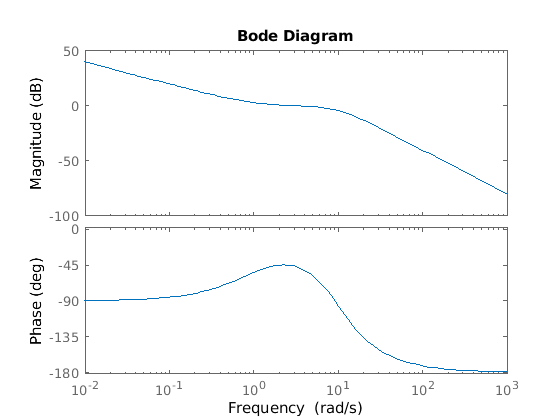


bode(G)

[mag,phase,wout] = bode(G,20);
mag =  mag * .5 

mag = 0.1141

phase = deg2rad(phase) + pi %converting from cos to sin

phase = 0.7677

### Question 2


$$G\left(s\right)=\frac{200s+10}{s\left(s+1\right)\left(s^2 +16s+100\right)}$$



$$G\left(s\right)=\frac{10\left(\frac{s}{\ldotp 05}+1\right)}{s\left(s+1\right)\left(s^2 +16s+100\right)}$$



$$G\left(s\right)=\frac{1}{10}\frac{\left(\frac{s}{\ldotp 5}+1\right)}{s\left(s+1\right)\left(\frac{s^2 }{{10}^2 }+\frac{1\ldotp 6}{10}s+1\right)}$$


Poles: 

Constant Gain: $K=\frac{1}{10}$ BLUE

20*log10(K) = -20 db

Pole at Origin: $\frac{1}{\left(s\right)}$ PURPLE

First Order Pole:$\frac{1}{\left(s+1\right)}$ YELLOW


$$\omega_n =1$$


First Order Pole:$\left(\frac{s}{\ldotp 05}+1\right)$ RED


$$\omega_n =\ldotp 5$$


Second Order: $\frac{1}{\left(\frac{s^2 }{{10}^2 }+\frac{1\ldotp 6}{10}s+1\right)}$ GREEN


$$\omega_n =10$$


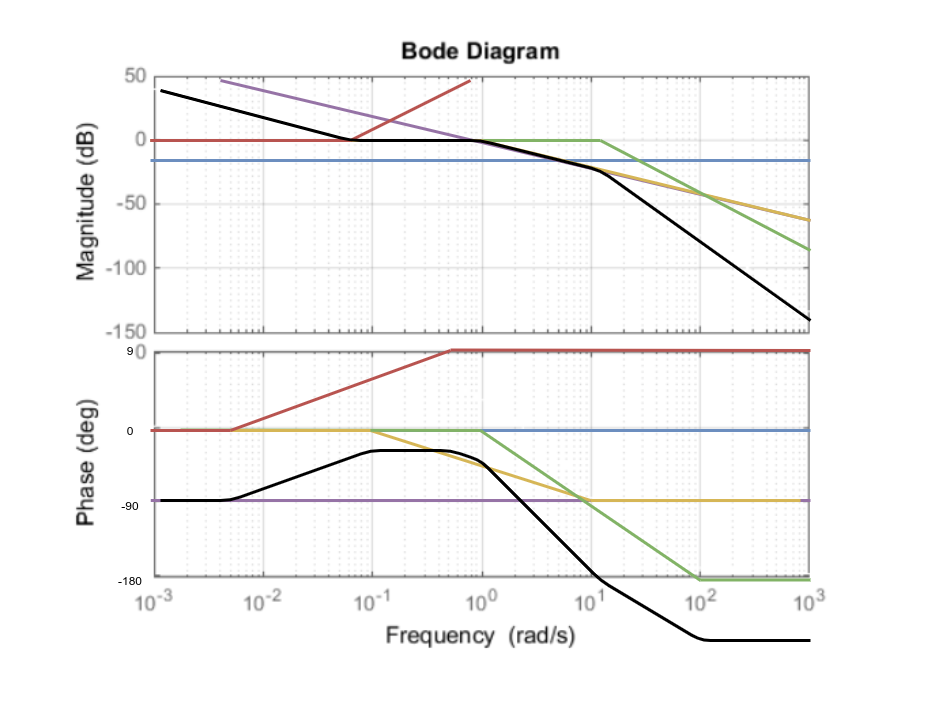

### Question 3

#### a)

cg = 2 rad/s

cp =$\sqrt{3*4}$ =3.46 rad/s

Gm = 10 db

Pm = 40 deg

#### b) 

System is stable as both Gm and Pm are positive

#### c) 

clear;
p=pi;
zeta = 40/100

zeta = 0.4000

z=zeta;
syms pi zeta real; 
Mp = exp(-zeta*pi/sqrt(1-zeta^2))

$$Mp = {\mathrm{e}}^{-\frac{\pi \,\zeta }{{\left(1-\zeta^{2}\right)}^{0.5000}}}$$

Mp = subs(Mp,[pi,zeta],[p,z])

$$Mp = 0.2538$$

#### d)

the inital slope of of the curve is -20dB/dec and indicates the precense of one pole at the origin

### Question 4

clear;
Pm = 30 %deg

Pm = 30

Wg = 15 %rad/s

Wg = 15

Kg = 1 

Kg = 1


p = pi;
zeta = 30/100

zeta = 0.3000

z=zeta;
syms pi zeta real; 
Mp = exp(-zeta*pi/sqrt(1-zeta^2))

$$Mp = {\mathrm{e}}^{-\frac{\pi \,\zeta }{{\left(1-\zeta^{2}\right)}^{0.5000}}}$$

Mp = subs(Mp,[pi,zeta],[p,z])

$$Mp = 0.3723$$


P_desired = 45%

P_desired = 45


$$C=K\;\frac{\mathrm{Ts}+1}{\alpha \mathrm{Ts}+1}$$


P_max = P_desired-Pm

P_max = 15

alpha = (1-sind(P_max))/(1+sind(P_max))

alpha = 0.5888

T = 1/(sqrt(alpha)*Wg)

T = 0.0869

K = sqrt(alpha)/Kg

K = 0.7673


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



C = K*(T * s +1)/(alpha*T*s+1)

C =
 
  0.06667 s + 0.7673
  ------------------
    0.05116 s + 1
 
Continuous-time transfer function.

